## A két szimuláció összehasonlítása

Először is a következő kódrészlet meg fogja nyitni az első környezetet, ahol szimulálunk, majd lefuttatja a szimulációt, és elmenti az adatokat.

clc;
clear;

m = 5; % Robot mass in KG
r = 0.05; %radius of wheel in meter
J = 2; % Moment inertia of robot KG*m^2

open("TheoryTesting.slx");

Fontos, hogy a simulink modellt futtassuk le. Ezek után az adatokat átkonvertáljuk vektor formába.

t1 = out.SimA.Time;
y1 = out.SimA.Data;

Most térjünk át a másik modellre:

La=0.94; %H, inductance of the armature winding
Ra=1; %Ohm, resistance of the armature winding
K_b=0.0301; %V/rad/s the back emf constant 
K_t=0.0300; %Nm/Amp the torque constant
J = 2; % Moment inertia of robot KG*m^2
M = 5; % Robot mass in KG
c = 0; % Location of center of gravity of robot. x=d y=o in robot frame
R = 0.02;%radius of wheel in meter
L = 0.1;%distance between wheel in meter
tau_max = 0.0854;
open("onlab_2.slx");

Majd a lefuttatás után az adatok átalakítása:

t2 = out.SimB.Time;
y2 = out.SimB.Data;
t3 = out.Gerj.Time;
u = out.Gerj.Data;

Ezek után jön az adatok megjelenítése, amihez csinálunk gerjesztőjelet is, hogy ez is látható legyen. Ezt a szekciót lehet, hogy többször is le kell futtatni, hogy működjön.

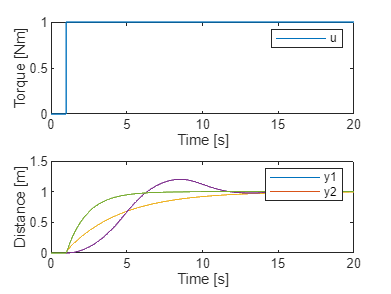

figure(1);
hold on;
subplot(2,1,1);
plot(t3,u);
grid on;
legend('u')
xlabel('Time [s]');
ylabel('Torque [Nm]');
grid off;
subplot(2,1,2);
plot(t1,y1);
grid on;
plot(t2,y2);
legend('y1','y2');
xlabel('Time [s]');
ylabel('Distance [m]');
grid off;
hold off;